data = readtable("no_load_shedding_sim.csv");


data = data(1:5:end, :);

data.Step(:) = data.Step(:)/5

data = 4355×61 table
    Step    Agent_ACLoad    Agent_ACLoad__MIN    Agent_ACLoad__MAX    Agent_PVGeneration    Agent_PVGeneration__MIN    Agent_PVGeneration__MAX    Agent_WindGeneration    Agent_WindGeneration__MIN    Agent_WindGeneration__MAX    Agent_DCLoad    Agent_DCLoad__MIN    Agent_DCLoad__MAX    Agent_LoadShedding    Agent_LoadShedding__MIN    Agent_LoadShedding__MAX    Agent_PeakPurchases    Agent_PeakPurchases__MIN    Agent_PeakPurchases__MAX    Agent_StandardPurchases    Agent_StandardPurchases__MIN    Agent_StandardPurchases__MAX    Agent_Off_PeakPurchases    Agent_Off_PeakPurchas



data.Power_bal = (data.Agent_PVGeneration+data.Agent_WindGeneration)-(data.Agent_ACLoad + data.Agent_DCLoad);
data.Power_bal_check = (data.Baseline_PVGeneration + data.Baseline_WindGeneration)-(data.Baseline_ACLoad + data.Baseline_DCLoad);

sum(data.Power_bal-data.Power_bal_check)

ans = 0


% data = data.Power_bal
% 
% % Assign the data to a variable in the workspace
% assignin('base', 'data', data);
% 
% % Run the App
% run('agent_vis.mlapp');

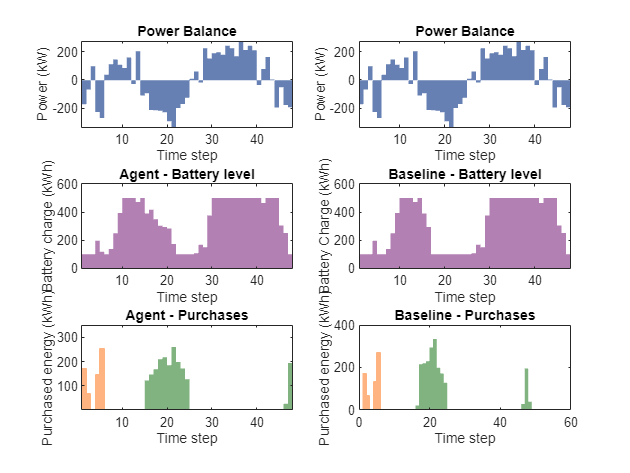

Error using matlab.internal.imagesci.wgifc
Can only append to GIF89a format GIFs.

Error in writegif (line 309)
matlab.internal.imagesci.wgifc(mat, map, filename,writemode,disposalmethod,delaytime,...

Error in imwrite (line 566)
        feval(fmt_s.write, da

% Create VideoWriter object
filename = 'test6.gif';
hFig = figure;

range = 48;
for t = 600:700
offset = t;



power = [0.4, 0.5, 0.7];
battery = [0.7, 0.5, 0.7];
off_peak = [0.5, 0.7, 0.5];
standard = [1, 0.7, 0.5];
peak     = [1, 0.35, 0.35];
% Subplot 1-1
% Subplot 1-1
subplot(3, 2,1);  % 4 rows, 2 columns, first subplot
sh = stairs(data.Power_bal(offset:offset + range), "Color",power);
fillStairs(sh,power)
title('Power Balance');
xlabel('Time step');
ylabel('Power (kW)');
%legend('Power balance');
xlim([1, range])

% Subplot 1-1
subplot(3, 2,3);  % 4 rows, 2 columns, first subplot
sh = stairs(data.Agent_Battery_level(offset:offset+range),"Color",battery);
fillStairs(sh,battery)
title('Agent - Battery level');
xlabel('Time step');
ylabel('Battery charge (kWh)');
%legend('Battery level');
xlim([1, range])
ylim([0,600])
% Subplot 1-1

subplot(3, 2,5);  % 4 rows, 2 columns, first subplot
sh = stairs(data.Agent_Off_PeakPurchases(offset:offset+range),"Color",off_peak);
fillStairs(sh,off_peak)
hold on
sh = stairs(data.Agent_StandardPurchases(offset:offset+range),"Color",standard);
fillStairs(sh,standard)
sh = stairs(data.Agent_PeakPurchases(offset:offset+range),"Color",peak);
fillStairs(sh,peak)
hold off
title('Agent - Purchases');
xlabel('Time step');
ylabel("Purchased energy (kWh)");
%legend("Peak purchases","Standard purchases","Off-peak purchases","Location","eastoutside");
xlim([1, range])
ylim([1,350])
% Subplot 1-2

subplot(3, 2,2);   % 4 rows, 2 columns, second subplot
sh = stairs(data.Power_bal(offset:offset + range),"Color",power);
fillStairs(sh,power)
title('Power Balance');
xlabel('Time step');
ylabel('Power (kW)');
%legend('Power balance');
xlim([1, range])

subplot(3, 2,4);   % 4 rows, 2 columns, second subplot
sh = stairs(data.Baseline_Battery_level(offset:offset+range),"Color",battery);
fillStairs(sh,battery)
title('Baseline - Battery level');
xlabel('Time step');
ylabel('Battery Charge (kWh)');
%legend('Battery Level');
xlim([1, range])
ylim([0,600])

subplot(3,2,6);   % 4 rows, 2 columns, second subplot
sh = stairs(data.Baseline_Off_PeakPurchases(offset:offset+range),"Color",off_peak);
fillStairs(sh,off_peak)
hold on
sh = stairs(data.Baseline_StandardPurchases(offset:offset+range),'Color', standard);
fillStairs(sh,standard)
sh=stairs(data.Baseline_PeakPurchases(offset:offset+range),"Color",peak);
fillStairs(sh,peak)
hold off

% Get the (y,x) coordinates from the original inputs or from  
% the xdata and ydata properties of the stair object which will
% always be row vectors.  

title('Baseline - Purchases');
xlabel('Time step');
ylabel('Purchased energy (kWh)');
%legend("Peak purchases","Standard purchases","Off-peak purchases","Location","eastoutside");
    % Capture the plot as a frame
    % Capture the plot as a frame
    % Capture the plot as a frame
    frame = getframe(hFig);
    img = frame2im(frame);
    
    % Convert the frame to an indexed image
    [imind, cm] = rgb2ind(img, 256);
    
    % Write to the GIF File
    if t == 1
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
    end
end

2100

ans = 2100

%510
offset = 650

offset = 650

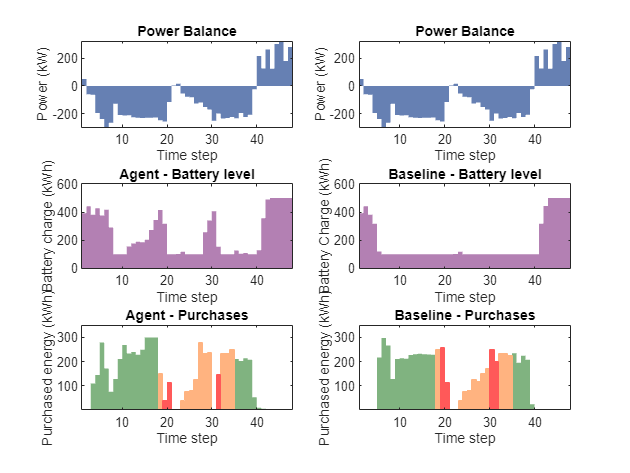

%offset = 400 ;
range = 48;
figure;

%% First main plot with subplots
% Main title for the first set of subplots
power = [0.4, 0.5, 0.7];
battery = [0.7, 0.5, 0.7];
off_peak = [0.5, 0.7, 0.5];
standard = [1, 0.7, 0.5];
peak     = [1, 0.35, 0.35];

% Subplot 1-1
subplot(3, 2,1);  % 4 rows, 2 columns, first subplot
sh = stairs(data.Power_bal(offset:offset + range), "Color",power);
fillStairs(sh,power)
title('Power Balance');
xlabel('Time step');
ylabel('Power (kW)');
%legend('Power balance');
xlim([1, range])

% Subplot 1-1
subplot(3, 2,3);  % 4 rows, 2 columns, first subplot
sh = stairs(data.Agent_Battery_level(offset:offset+range),"Color",battery);
fillStairs(sh,battery)
title('Agent - Battery level');
xlabel('Time step');
ylabel('Battery charge (kWh)');
%legend('Battery level');
xlim([1, range])
ylim([0,600])
% Subplot 1-1

subplot(3, 2,5);  % 4 rows, 2 columns, first subplot
sh = stairs(data.Agent_Off_PeakPurchases(offset:offset+range),"Color",off_peak);
fillStairs(sh,off_peak)
hold on
sh = stairs(data.Agent_StandardPurchases(offset:offset+range),"Color",standard);
fillStairs(sh,standard)
sh = stairs(data.Agent_PeakPurchases(offset:offset+range),"Color",peak);
fillStairs(sh,peak)
hold off
title('Agent - Purchases');
xlabel('Time step');
ylabel("Purchased energy (kWh)");
%legend("Peak purchases","Standard purchases","Off-peak purchases","Location","eastoutside");
xlim([1, range])
ylim([1,350])
% Subplot 1-2

subplot(3, 2,2);   % 4 rows, 2 columns, second subplot
sh = stairs(data.Power_bal(offset:offset + range),"Color",power);
fillStairs(sh,power)
title('Power Balance');
xlabel('Time step');
ylabel('Power (kW)');
%legend('Power balance');
xlim([1, range])

subplot(3, 2,4);   % 4 rows, 2 columns, second subplot
sh = stairs(data.Baseline_Battery_level(offset:offset+range),"Color",battery);
fillStairs(sh,battery)
title('Baseline - Battery level');
xlabel('Time step');
ylabel('Battery Charge (kWh)');
%legend('Battery Level');
xlim([1, range])
ylim([0,600])

subplot(3,2,6);   % 4 rows, 2 columns, second subplot
sh = stairs(data.Baseline_Off_PeakPurchases(offset:offset+range),"Color",off_peak);
fillStairs(sh,off_peak)
hold on
sh = stairs(data.Baseline_StandardPurchases(offset:offset+range),'Color', standard);
fillStairs(sh,standard)
sh=stairs(data.Baseline_PeakPurchases(offset:offset+range),"Color",peak);
fillStairs(sh,peak)
hold off

% Get the (y,x) coordinates from the original inputs or from  
% the xdata and ydata properties of the stair object which will
% always be row vectors.  
xlim([1, range])
ylim([1,350])
title('Baseline - Purchases');
xlabel('Time step');
ylabel('Purchased energy (kWh)');

%legend("Peak purchases","Standard purchases","Off-peak purchases","Location","eastoutside");

function fillStairs(sh, color)
    bottom = -1.5; %identify bottom; or use min(sh.YData)
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    % plot(x,y,'y:') %should match stair plot
    % Fill area
    fill([x,fliplr(x)],[y,bottom*ones(size(y))], color,'EdgeColor','none')
end
